path = "C:\Users\lenovo\OneDrive\Pulpit\IB\Magisterskie\Semestr2\DADM\lab5\abr_signal3.mat";

file = load(path);

Dla każdej struktury wyznaczamy maksimum fali V i następujące po niej minimum. Następnie obliczamy V-pp, a potem stosunek V-pp do mean. W pewnym momencie stosunek będzie bardzo mały i wtedy należy stwierdzić, że fala V jest nie wykryta. Miejsce wystąpienia fali zwiększa się dla każdego kolejnego natężenia. Należy rozpocząć poszukiwanie maksimum od miejsca wystąpienia maksimum z poprzedniego natężenia.

data = file.abr_signal3

data = 10×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}



db = data{2}.dB

db = 110

signal = data{1}.data;

fp = 100000;

ones_arr = transpose(signal(length(signal)-1)*ones(1,24));
%signal =  cat(1, signal, )
signal = [signal; ones_arr];

t = 0:1/fp:(length(signal)-1)*(1/fp);
t = t * 1000;

[swa,swd] = swt(signal,6,'bior5.5');

swa = swa(6, :)

swa =   -54.3804  -54.9118  -55.4848  -56.1018  -56.7619  -57.4620  -58.1975  -58.9616  -59.7447  -60.5330  -61.3109  -62.0665  -62.7886  -63.4657  -64.0886  -64.6484  -65.1355  -65.5421  -65.8637  -66.0972  -66.2457  -66.3146  -66.3100  -66.2405  -66.1162  -65.9484  -65.7491  -65.5264  -65.2866  -65.0366  -64.7799  -64.5193  -64.2581  -63.9941  -63.7254  -63.4535  -63.1763  -62.8895  -62.5919  -62.2817  -61.9563  -61.6152  -61.2569  -60.8785  -60.4810  -60.0656  -59.6341  -59.1885  -58.7305  -58.2648



[max, idx_max] = findpeaks(swa)

max =    47.0699  156.0084  121.0599   -8.3360  -45.2995


idx_max =    163   401   621   794   985


[min, idx_min] = findpeaks(-swa)

min =    66.3146   26.4070  -28.8450   52.4367   66.9189


idx_min =     22   287   518   722   924



idx_V = find(idx_max > 550 & idx_max < 700)

idx_V = 3

V_max = max(idx_V)

V_max = 121.0599


idx_V_min = find(idx_min > idx_max(idx_V))

idx_V_min =      4     5


idx_V_min = idx_V_min(1)

idx_V_min = 4

V_min = swa(idx_min(idx_V_min))

V_min = -52.4367


V_pp = V_max - V_min

V_pp = 173.4965

V_mean = abs(mean(swa))

V_mean = 12.5156


sto = V_pp / V_mean

sto = 13.8624

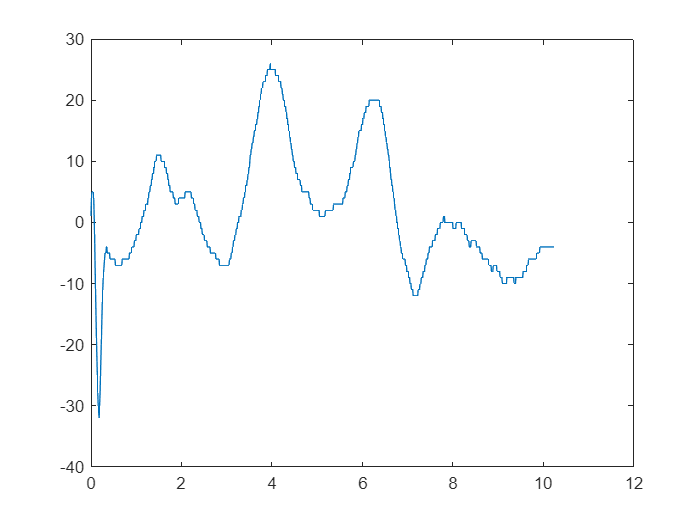

figure
plot(t, signal)

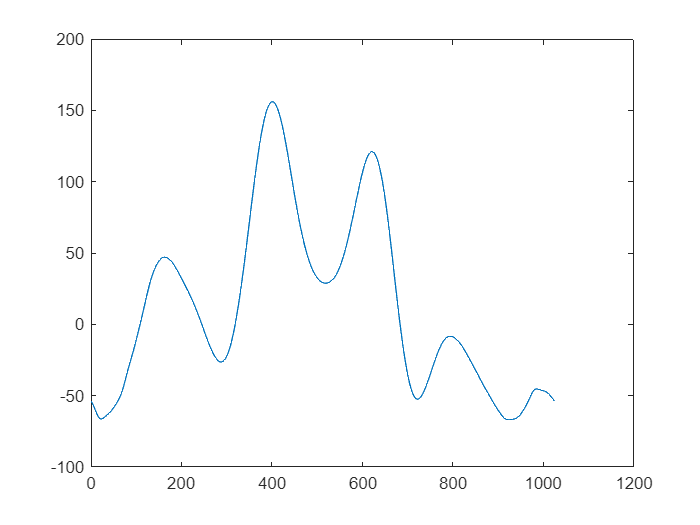

figure 
plot(swa)